Data

RequiredMaps =      100000.00


load("C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\2D\DL\AllSolvedData" + RequiredMaps + ".mat", 'AllSolvedData')
head(AllSolvedData)

          Var1              Var2     
    ________________    _____________

    1×1 occupancyMap    {11×3 double}
    1×1 occupancyMap    {11×3 double}
    1×1 occupancyMap    {16×3 double}
    1×1 occupancyMap    {10×3 double}
    1×1 occupancyMap    {28×3 double}
    1×1 occupancyMap    { 8×3 double}
    1×1 occupancyMap    {18×3 double}
    1×1 occupancyMap    {18×3 double}



Database = AllSolvedData;
statespace = stateSpaceSE2;
statespace.StateBounds = [[0 20]; [0 20]; [-3.1416 3.1416]];



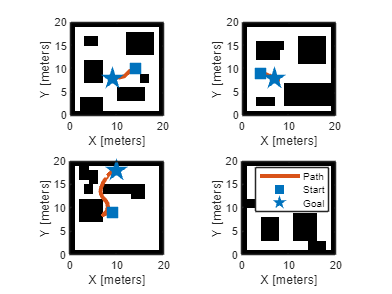

figure
for i=1:4
    subplot(2,2,i)    
    ind = randi(height(Database)); % Select a random sample
    map = Database(ind,:).Var1; % Get map from Map column of the table
    pathStates = Database(ind,:).Var2{1}; % Get path from Path column of the table
    start = pathStates(1,:); 
    goal = pathStates(end,:);
    
    % Plot the data
    show(map); 
    hold on
    plot(pathStates(:,1),pathStates(:,2),plannerLineSpec.path{:})
    plot(start(1),start(2),plannerLineSpec.start{:})
    plot(goal(1),goal(2),plannerLineSpec.goal{:})
    title("")
end
legend

mpnet = mpnetSE2;
mpnet.LossWeights = [100 100 0];
mpnet.EncodingSize = [9 9];

split = 0.8;

trainData = Database(1:int32(split*end),:)

trainData = 71198×2 table
          Var1              Var2     
    ________________    _____________

    1×1 occupancyMap    {11×3 double}
    1×1 occupancyMap    {11×3 double}
    1×1 occupancyMap    {16×3 double}
    1×1 occupancyMap    {10×3 double}
    1×1 occupancyMap    {28×3 double}
    1×1 occupancyMap    { 8×3 double}
    1×1 occupancyMap    {18×3 double}
    1×1 occupancyMap    {18×3 double}
    1×1 occupancyMap    {15×3 double}
    1×1 occupancyMap    { 7×3 double}
    1×1 occupancyMap    {21×3 double}
    1×1 occupancyMap    {13×3 double}
    1×1 occupancyMap    {12×3 double}
    1×1 occupancyMap    { 9×3 double}
    1×1 occupancyMap    {11×3 double}
    1×1 occupancyMap    {31×3 double}


validationData = Database(int32(split*end)+1:end,:)

validationData = 17799×2 table
          Var1              Var2     
    ________________    _____________

    1×1 occupancyMap    { 8×3 double}
    1×1 occupancyMap    {15×3 double}
    1×1 occupancyMap    {12×3 double}
    1×1 occupancyMap    { 8×3 double}
    1×1 occupancyMap    {22×3 double}
    1×1 occupancyMap    {22×3 double}
    1×1 occupancyMap    {10×3 double}
    1×1 occupancyMap    {10×3 double}
    1×1 occupancyMap    {20×3 double}
    1×1 occupancyMap    {20×3 double}
    1×1 occupancyMap    { 9×3 double}
    1×1 occupancyMap    {14×3 double}
    1×1 occupancyMap    {18×3 double}
    1×1 occupancyMap    {19×3 double}
    1×1 occupancyMap    {17×3 double}
    1×1 occupancyMap    {22×3 double}


dsTrain = mpnetPrepareData(trainData,mpnet);
dsValidation = mpnetPrepareData(validationData,mpnet);

preparedDataSample = read(dsValidation);
preparedDataSample(1,:)

ans = 1×2 cell array
    {[0.58 0.56 1.00 0.50 0.59 0.56 1.00 0.50 0.34 0.40 0.12 0 0.34 0.40 0.40 0.40 0.34 0.40 0.53 0.27 0.27 0.40 0.75 0.78 0.75 0.40 0.40 0.68 0.65 0.65 0.52 0.48 0.48 0.58 0.40 0.40 0.78 1.00 0.73 0.42 0.36 0.36 0.54 0.40 0.40 0.78 0.91 0.61 0.31 0.61 0.74 0.73 0.40 0.40 0.61 0.53 0.56 0.31 0.61 0.99 0.78 0.40 0.40 0.48 0.14 0.53 0.65 0.77 0.85 0.54 0.40 0.31 0.36 0.14 0.53 0.78 0.78 0.78 0.47 0.31 0.34 0.40 0.12 0.40 0.40 0.40 0.40 0.40 0.34]}    {[0.58 0.56 0.98 0.38]}


options = trainingOptions("adam",...
        MiniBatchSize=2048,...
        MaxEpochs=50,...
        Shuffle="every-epoch",...
        ValidationData=dsValidation,...
        ValidationFrequency=2000,...
        Plots="training-progress");

    % Train network
[m,systemview] = memory;
sprintf('%.0f MB',m.MemUsedMATLAB/(1024^2))

ans = '6884 MB'

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _________    _____    ___________    _________    ____________    ______________
            0        0       00:00:11        0.001                            48.145
            1        1       00:00:11        0.001          48.229                  
           50        1       00:00:20        0.001         0.89255                  
          100        1       00:00:22        0.001         0.44006                  
          150        1       00:00:25        0.001          0.3036                  
          200        1       00:00:28        0.001         0.24019                  
          250        1       00:00:31        0.001         0.19591                  
          300        1       00:00:34        0.001         0.16547                  
          350        1       00:00:37        0.001         0.15317                  
          400        1       00:00:40        0.001         0.1339

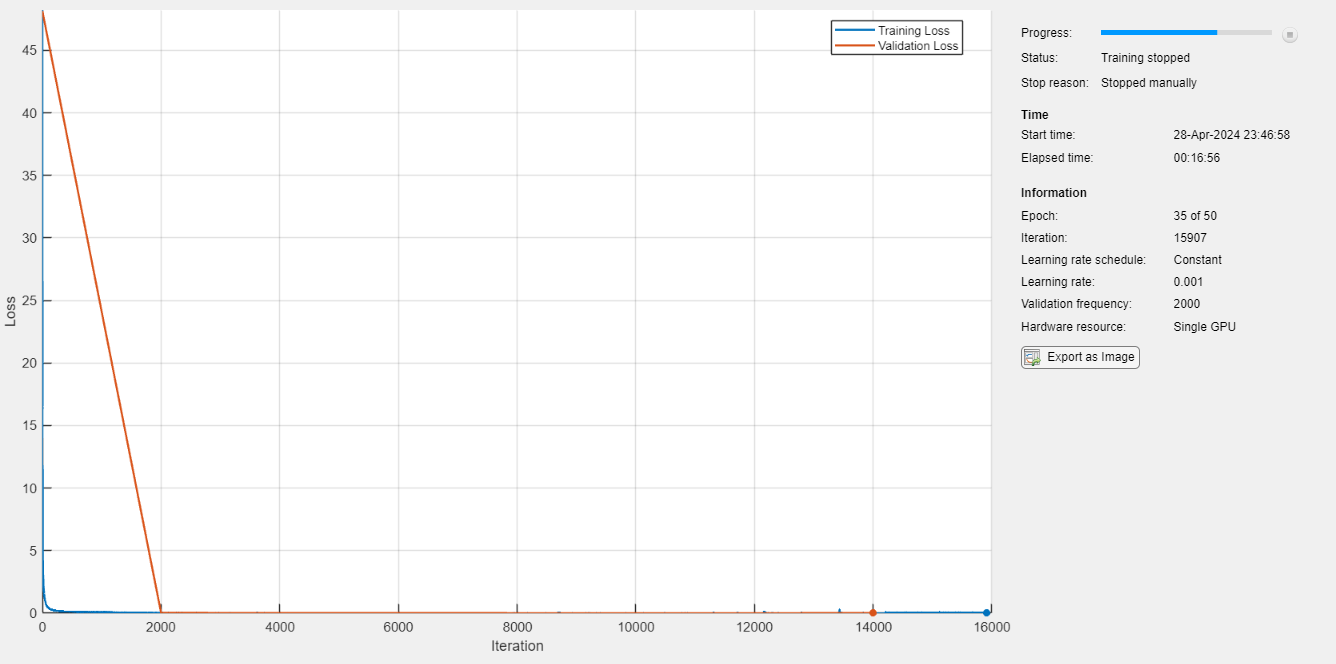

tic
[net, info] = trainnet(dsTrain, mpnet.Network, @mpnet.loss, options);

toc

Elapsed time is 1019.677931 seconds.


[m,systemview] = memory;S
sprintf('%.0f MB',m.MemUsedMATLAB/(1024^2))

ans = '9715 MB'

    % Update Network property of mpnet object with net
mpnet.Network = net;


mpnet

mpnet =   mpnetSE2 with properties:

     StateBounds: [3×2 double]
     LossWeights: [100.00 100.00 0]
    EncodingSize: [9.00 9.00]
       NumInputs: 89.00
      NumOutputs: 4.00
         Network: [1×1 dlnetwork]


save("C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\2D\DL\mpnet.mat", "mpnet")

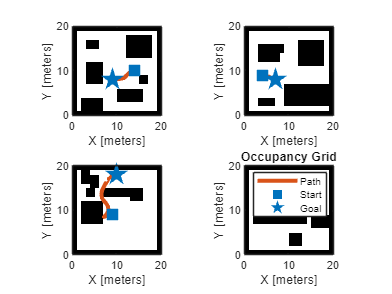



stateSamplerDL = stateSamplerMPNET(statespace,mpnet);

ind = randi(height(validationData));
map = validationData(ind,:).Var1;
start = double(validationData(ind,:).Var2{1,:}(1,:));
goal = double(validationData(ind,:).Var2{1,:}(end,:));

show(map)


stateSamplerDL.Environment = map;
stateSamplerDL.StartState = start;
stateSamplerDL.GoalState = goal;
stateSamplerDL

stateSamplerDL =   stateSamplerMPNET with properties:

               StateSpace: [1×1 stateSpaceSE2]
    MotionPlanningNetwork: [1×1 mpnetSE2]
              Environment: [1×1 occupancyMap]
               StartState: [7.00 18.00 0]
                GoalState: [18.00 11.00 0]
        MaxLearnedSamples: 50.00
            GoalThreshold: 1.00


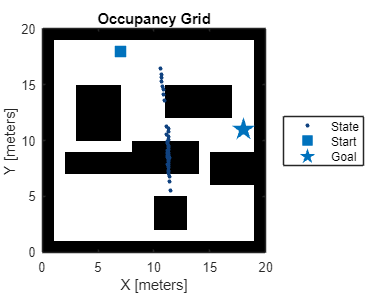

numSamples =50;
stateSamplerDL.MaxLearnedSamples = 50;
samples = sample(stateSamplerDL, numSamples);
figure
show(map);
hold on;
plot(samples(:,1),samples(:,2),plannerLineSpec.state{:})
plot(start(1),start(2),plannerLineSpec.start{:});
plot(goal(1),goal(2),plannerLineSpec.goal{:});
legend(Location="eastoutside")

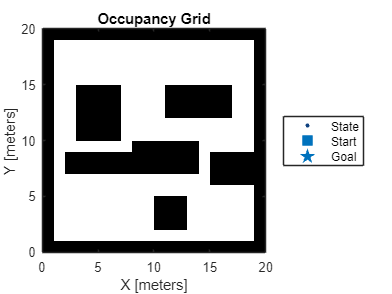

stateValidator = validatorOccupancyMap(statespace,Map=map);
stateValidator.ValidationDistance = 0.1;
show(map)

stateValidator

stateValidator =   validatorOccupancyMap with properties:

                   Map: [1×1 occupancyMap]
            StateSpace: [1×1 stateSpaceSE2]
             XYIndices: [1.00 2.00]
    ValidationDistance: 0.10


start

start =           7.00         18.00             0


goal

goal =          18.00         11.00             0


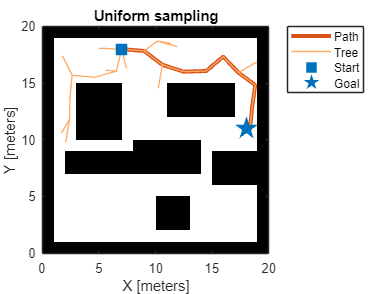


% Create RRT* planner with default uniform sampler
plannerUniformSampling = plannerRRTStar(statespace,stateValidator,MaxConnectionDistance=2,StateSampler=stateSamplerUniform(statespace));
[pathUniformSampling,solutionInfoUniformSampling] = plan(plannerUniformSampling,start,goal);

% Visualize results for uniform sampling
figure
show(map)
hold on;
plot(pathUniformSampling.States(:,1),pathUniformSampling.States(:,2),plannerLineSpec.path{:})
plot(solutionInfoUniformSampling.TreeData(:,1),solutionInfoUniformSampling.TreeData(:,2),plannerLineSpec.tree{:})
plot(start(1),start(2),plannerLineSpec.start{:});
plot(goal(1),goal(2),plannerLineSpec.goal{:});
legend(Location="northeastoutside")
title("Uniform sampling")

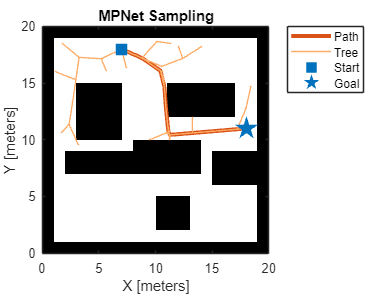

plannerDLSampling = plannerRRTStar(statespace,stateValidator,MaxConnectionDistance=2,StateSampler=stateSamplerDL);
[pathDLSampling,solutionInfoDLSampling] = plan(plannerDLSampling,start,goal);

% Visualize results with deep learning based sampling
figure
show(map);
hold on;
plot(pathDLSampling.States(:,1),pathDLSampling.States(:,2),plannerLineSpec.path{:})
plot(solutionInfoDLSampling.TreeData(:,1),solutionInfoDLSampling.TreeData(:,2),plannerLineSpec.tree{:})
plot(start(1),start(2),plannerLineSpec.start{:})
plot(goal(1),goal(2),plannerLineSpec.goal{:})
legend(Location="northeastoutside")
title("MPNet Sampling")


pathDLSampling.States

ans =           7.00         18.00             0
          8.80         17.21         -1.19
         10.43         16.10         -2.22
         10.78         14.67         -2.36
         10.92         12.68         -2.36
         11.13         10.69         -2.36
         11.27         10.44         -2.36
         13.25         10.60         -1.66
         15.23         10.77         -0.97
         17.21         10.93         -0.28


% Number of runs to benchmark the planner
runCount = 30;

% Create plannerBenchmark object
pb = plannerBenchmark(stateValidator,start,goal);

% Create function handles to create planners for uniform sampling and deep
% learning-based sampling
plannerUniformSamplingFcn = @(stateValidator)plannerRRTStar(stateValidator.StateSpace,stateValidator,MaxConnectionDistance=10);
plannerMPNetSamplingFcn = @(stateValidator)plannerRRTStar(stateValidator.StateSpace,stateValidator,MaxConnectionDistance=10,StateSampler=stateSamplerDL);

% Create plan function
plnFcn = @(initOut,s,g)plan(initOut,s,g);

% Added both planners to plannerBenchmark object
addPlanner(pb,plnFcn,plannerUniformSamplingFcn,PlannerName="Uniform");
addPlanner(pb,plnFcn,plannerMPNetSamplingFcn,PlannerName="MPNet");

% Run planners for specified runCount
runPlanner(pb,runCount)

Initializing Uniform ...
Done.
Planning a path from the start pose (7 18 0) to the goal pose (18 11 0) using Uniform.
Executing run 1.
Executing run 2.
Executing run 3.
Executing run 4.
Executing run 5.
Executing run 6.
Executing run 7.
Executing run 8.
Executing run 9.
Executing run 10.
Executing run 11.
Executing run 12.
Executing run 13.
Executing run 14.
Executing run 15.
Executing run 16.
Executing run 17.
Executing run 18.
Executing run 19.
Executing run 20.
Executing run 21.
Executing run 22.
Executing run 23.
Executing run 24.
Executing run 25.
Executing run 26.
Executing run 27.
Executing run 28.
Executing run 29.
Executing run 30.
Initializing MPNet ...
Done.
Planning a path from the start pose (7 18 0) to the goal pose (18 11 0) using MPNet.
Executing run 1.
Executing run 2.
Executing run 3.
Executing run 4.
Executing run 5.
Executing run 6.
Executing run 7.
Executing run 8.
Executing run 9.
Executing run 10.
Executing run 11.
Executing run 12.
Executing run 13.
Executing ru

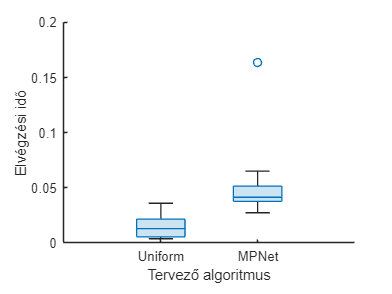

figure
show(pb,"executionTime")
xlabel("Tervező algoritmus")
ylabel("Elvégzési idő")

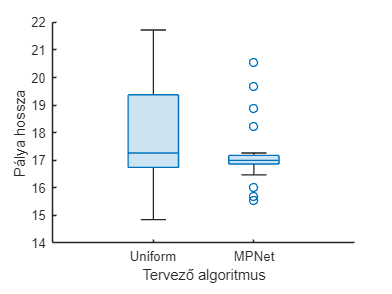

figure
show(pb,"pathLength")
xlabel("Tervező algoritmus")
ylabel("Pálya hossza")

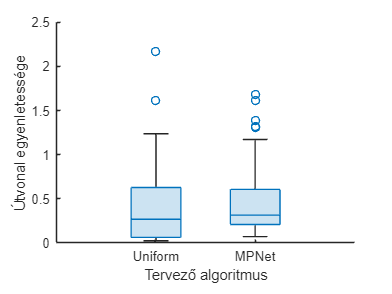

figure
show(pb,"smoothness")
xlabel("Tervező algoritmus")
ylabel("Útvonal egyenletessége")